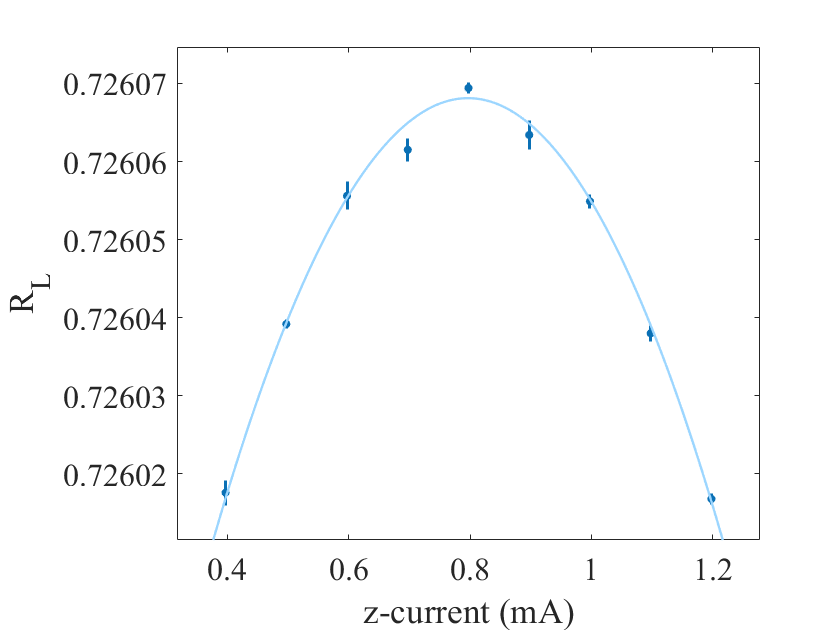


close all;
clear all;

maindir = ['\\Artemis-pc\Data\2026-09-17\' ...
    'zFit'];
save_data = 1;

xc_approx = 797*1e-3;
x = 1e-3*([397.5 497.5 597.5 ...
    697.5 797.5 897.5 ...
    997.5 1097.5 1197.5 ...
    ]);
y = [0.7260176 0.7260392 0.7260556 ...
    0.7260615 0.7260694 0.7260634 ...
    0.7260549 0.7260380 0.7260168 ...
    ];
err = 1e-7*[16 6 18 ...
    15 7 18 ...
    9 10 7 ...
    ];

% x = 1e-3*([2310 2410 2510 ...
%     2610 2710 2810 ...
%     2910 3010 2210]);
% y = [0.7260524 0.7260603 0.7260660...
%     0.7260650 0.7260622 0.7260541 ...
%     0.7260455 0.7260311 0.7260426];
% err = 1e-7*[15 8 10 ...
%       11 12 17 ...
%       15 14 17];

w = 1./err.^2;

f1 = figure; hold on;
errorbar(x,y,err,'.','CapSize',0,...
    'MarkerSize',14,'LineWidth',1.5,...
    'Color',[0.04,0.44,0.71]);

margin_per = 0.1;

xmin = min(x)-margin_per*(max(x)-min(x));
xmax = max(x)+margin_per*(max(x)-min(x));

ymin = min(y)-margin_per*(max(y)-min(y));
ymax = max(y)+margin_per*(max(y)-min(y));

xlim([xmin xmax]);
ylim([ymin ymax]);

set(gcf,'Visible','on');

%% 拟合: '无标题拟合 1'。
[xData, yData, weights] = prepareCurveData( x, y, w );

% 设置 fittype 和选项。
ft = fittype( 'a*(x-x0)^2+R0', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.726 0 xc_approx];
opts.Weights = weights;

% 对数据进行模型拟合。
[fitted, gof] = fit( xData, yData, ft, opts );
interval = confint(fitted);
a = fitted.a;
a_err = abs(interval(1,2)-interval(2,2))/4;
R0 = fitted.R0;
R0_err = abs(interval(1,1)-interval(2,1))/4;
x0 = fitted.x0;
x0_err = abs(interval(1,3)-interval(2,3))/4;

% 绘制数据拟合图。
l = plot(fitted);
l.LineWidth = 1.2;
l.Color = [0.61 0.84 1];

legend off;

set(gca,'FontName','times new roman',...
    'FontSize',16);
xlabel('z-current (mA)');
ylabel('R_L');
box on;


if save_data == 1
    savefig(f1,[maindir,'.fig']);
    saveas(f1,[maindir,'.png']);
    %
    save([maindir,'.mat']);
end